# MECH 6323 - HW 07

Author: Jonas Wagner

Date: 2022-05-08

## Problem 1

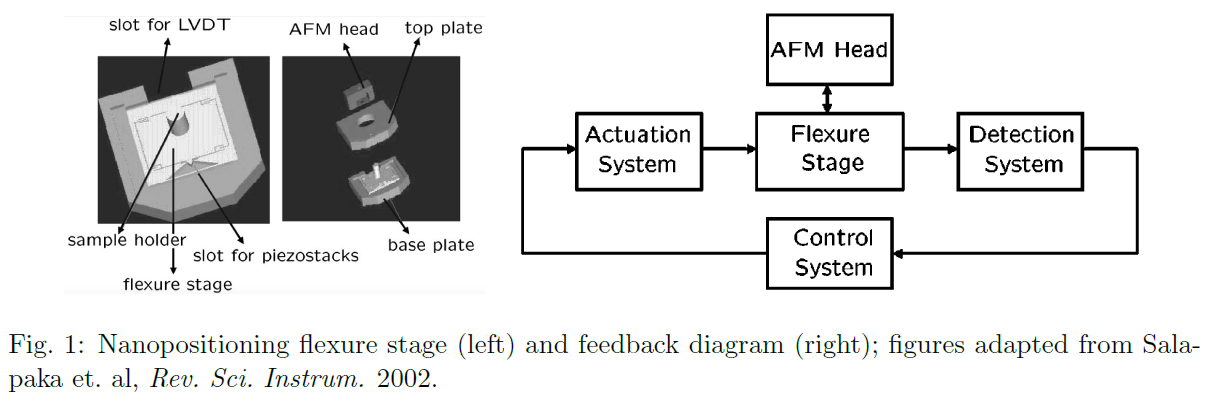

clear
close all

### Part a

Load data: G, w, nano_sp.Gfr

% load('C:\Users\Jonas\OneDrive - The University of Texas at Dallas\2022_Spring\MECH6323\Homework\HW07\HW7-matfiles\npresp.mat')
nano_rsp = load('npresp.mat')

nano_rsp = struct with fields:
    Gfr: [1×1 frd]
      w: [1748×1 double]
      G: [1×1×1748 double]


omega_min = min(nano_rsp.w);
omega_max = max(nano_rsp.w);

#### Estimate system transfer function

tf_order = 6;
G_sys = fitfrd(nano_rsp.Gfr, tf_order)

G_sys =
 
  A = 
          x1     x2     x3     x4     x5     x6
   x1  -1468   8540  -8540   8540  -8540   4270
   x2  -4681   6559  -3757   3757  -3757   1878
   x3  -2174   4348  -7150   9952  -9952   4976
   x4  -4695   9390  -9390   6588  -3786   1893
   x5  -1687   3374  -3374   3374  -6176   4489
   x6  -3428   6856  -6856   6856  -6856  625.7
 
  B = 
          u1
   x1  5.156
   x2  11.36
   x3   16.7
   x4  18.15
   x5  11.59
   x6  11.18
 
  C = 
           x1      x2      x3      x4      x5      x6
   y1   114.1  -228.1   228.1  -228.1   228.1  -114.1
 
  D = 
            u1
   y1  0.08876
 
Continuous-time state-space model.



G_sys_tf = tf(G_sys)

G_sys_tf =
 
  0.08876 s^6 - 876.1 s^5 + 1.136e07 s^4 - 4.345e10 s^3 + 4.097e14 s^2 - 2.095e17 s + 3.082e21
  --------------------------------------------------------------------------------------------
       s^6 + 1021 s^5 + 7.856e07 s^4 + 5.129e10 s^3 + 1.342e15 s^2 + 3.65e17 s + 5.421e21
 
Continuous-time transfer function.



G_sys_zpk = zpk(G_sys)

G_sys_zpk =
 
  0.088762 (s^2 + 526.7s + 9.417e06) (s^2 + 276.6s + 4.494e07) (s^2 - 1.067e04s + 8.207e07)
  -----------------------------------------------------------------------------------------
         (s^2 + 186.2s + 6.029e06) (s^2 + 482.7s + 1.6e07) (s^2 + 352.5s + 5.621e07)
 
Continuous-time zero/pole/gain model.



#### Bode Diagram Data

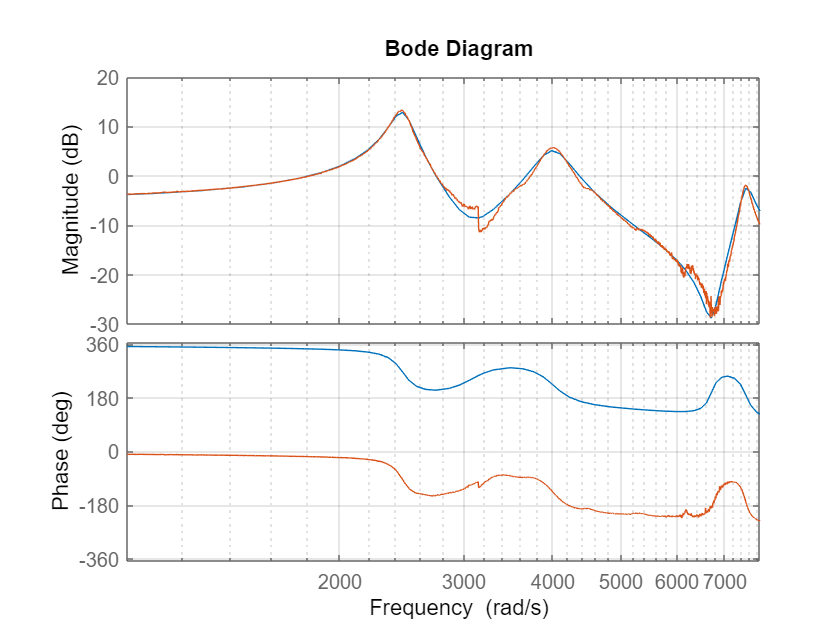

figure()
bode(G_sys)
hold on
bode(nano_rsp.Gfr)
grid on
xlim([omega_min, omega_max])

Clearly this plot is a good estimation for the frequency response of the system, noting that the phase of the system is offset by a 360 degree phase shift (which implies a need for another set of integrators)

### Part b

PM_min = 75;
opt = pidtuneOptions( ...
    'PhaseMargin', PM_min, ...
    'DesignFocus', 'disturbance-rejection' ...
    )

opt =   pidtune with properties:

         PhaseMargin: 75
    NumUnstablePoles: 0
         DesignFocus: 'disturbance-rejection'


[C_pi, info] = pidtune(G_sys, 'pi', opt)

C_pi =
 
        1 
  Ki * ---
        s 

  with Ki = 240
 
Continuous-time I-only controller.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 136.5946
           PhaseMargin: 88.9408


allmargin(C_pi * G_sys)

ans = struct with fields:
     GainMargin: [2.3213 31.8215 13.3190]
    GMFrequency: [2.4472e+03 3.2556e+03 3.7346e+03]
    PhaseMargin: 88.9408
    PMFrequency: 136.5946
    DelayMargin: 0.0114
    DMFrequency: 136.5946
         Stable: 1


#### Bode Diagram of Margin

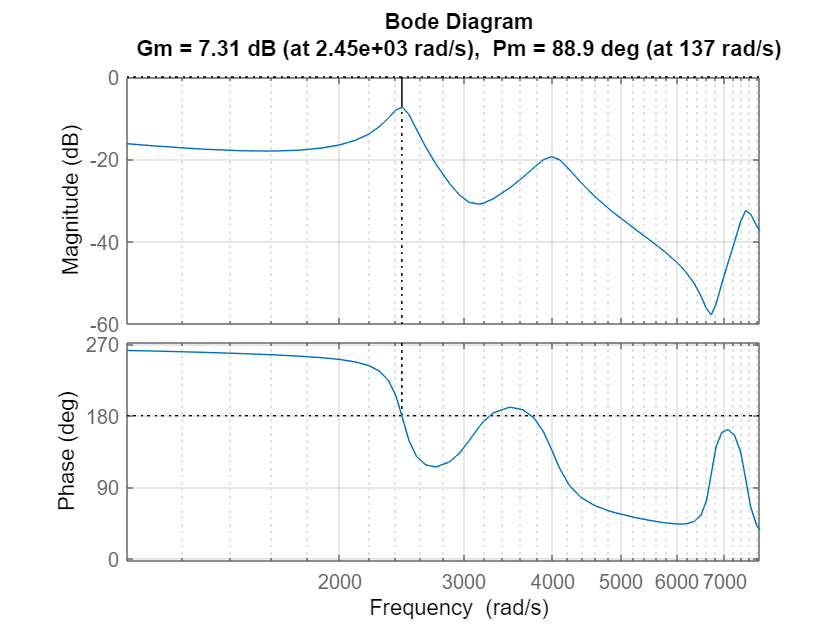

figure
margin(C_pi * G_sys_tf)
grid on
xlim([omega_min, omega_max])

As a result, the single only integral controller is a pretty weird result. However, looking at the results it does make sense.

#### Double Integrator implimenation

Instead we can also include an additional integrator into the controller, i.e.

G_int = tf(1,[1, 0]);
[C_pi_int, info] = pidtune(G_int * G_sys, 'pi', opt)

C_pi_int =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 271, Ki = 1.06e+04
 
Continuous-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 159.0729
           PhaseMargin: 75.0000


allmargin(C_pi_int * G_int * G_sys)

ans = struct with fields:
     GainMargin: [0 2.0518 27.8933 11.9425]
    GMFrequency: [0 2.4457e+03 3.2626e+03 3.7282e+03]
    PhaseMargin: 75.0002
    PMFrequency: 159.0759
    DelayMargin: 0.0082
    DMFrequency: 159.0759
         Stable: 1


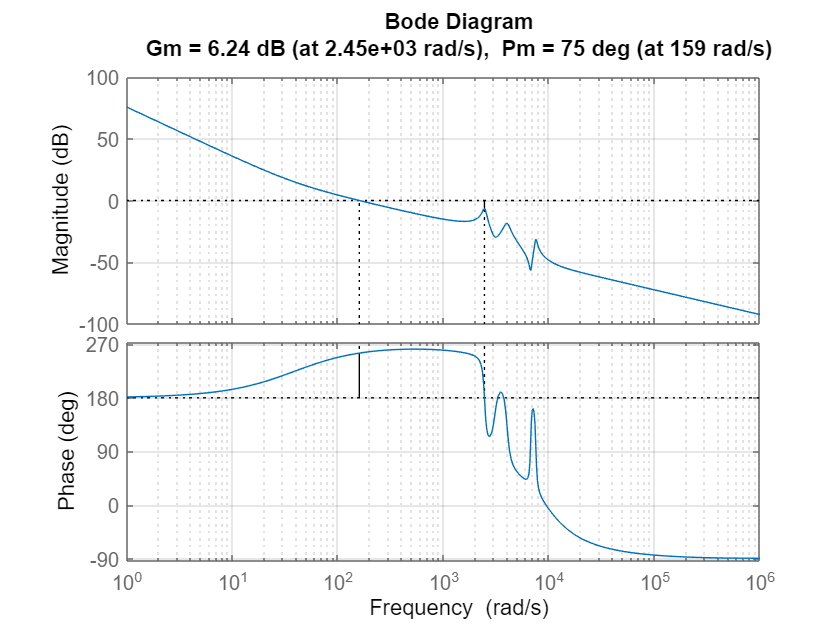

figure
margin(C_pi_int * G_int * G_sys)
grid on

#### Bandwidth Calculation

(I'm not 100% sure how this differs from the cross over frequency...)

% figure
% bode(C_pi * G_sys_tf)
% grid on
% xlim([omega_min, omega_max])

## Part c